** Load and Verify the Data**

clc; clear;

disp('STEP 0: Loading processed battery data...');

STEP 0: Loading processed battery data...



filePath = "C:\Users\Lenovo\Desktop\Battery_Pack_Design_Project_142\Data\battery_data_processed.mat";
load(filePath);

disp('✓ Data file loaded');

✓ Data file loaded



time    = time(:);
voltage = voltage(:);
current = current(:);

assert(numel(time)==numel(voltage) && numel(time)==numel(current), ...
    'Vector length mismatch');

disp(['✓ Samples loaded: ', num2str(numel(time))]);

✓ Samples loaded: 6000


**Enforce Current Convention**

disp('STEP 1: Checking current polarity...');

STEP 1: Checking current polarity...



if mean(current) < 0
    current = -current;
    disp('✓ Current inverted to positive-discharge');
else
    disp('✓ Current polarity already correct');
end

✓ Current polarity already correct


**Sampling Verification**

disp('STEP 2: Checking sample rate...');

STEP 2: Checking sample rate...



dt = mean(diff(time));
Fs = 1/dt;

disp(['✓ Mean dt = ', num2str(dt), ' s']);

✓ Mean dt = 0.1 s


disp(['✓ Sampling rate = ', num2str(Fs), ' Hz']);

✓ Sampling rate = 10 Hz


**Define Initial Guess**

disp('STEP 3: Defining initial parameter guess...');

STEP 3: Defining initial parameter guess...



theta0 = [
    mean(voltage);   % Em
    0.05;            % R0 (Ohm)
    0.01;            % R1
    10;              % C1
    0.02;            % R2
    100;             % C2
    0.005;           % R3
    500              % C3
];

disp('✓ Initial guess vector created');

✓ Initial guess vector created


disp(theta0);

    4.0265
    0.0500
    0.0100
   10.0000
    0.0200
  100.0000
    0.0050
  500.0000



**Define Bounds**

disp('STEP 4: Defining parameter bounds...');

STEP 4: Defining parameter bounds...



lb = [
    min(voltage);
    0.001;
    0.001;
    1;
    0.001;
    10;
    0.001;
    50
    ];

ub = [
    max(voltage);
    0.2;
    0.2;
    100;
    0.2;
    2000;
    0.2;
    5000
    ];

assert(numel(lb)==8 && numel(ub)==8, 'Bounds dimension error');

disp('✓ Bounds defined correctly');

✓ Bounds defined correctly


**Define Cost Function**

disp('STEP 5: Creating cost function...');

STEP 5: Creating cost function...



costFcn = @(theta) simulate_3RC(theta, time, current) - voltage;

disp('✓ Cost function ready');

✓ Cost function ready


**Run Optimization**

disp('STEP 6: Running nonlinear least squares estimation...');

STEP 6: Running nonlinear least squares estimation...



opts = optimoptions('lsqnonlin', ...
    'Algorithm','trust-region-reflective', ...
    'Display','iter', ...
    'MaxIterations',300);

[theta_hat,resnorm,residual,exitflag,output] = ...
    lsqnonlin(costFcn, theta0, lb, ub, opts);


                                            Norm of      First-order 
 Iteration  Func-count      Resnorm            step       optimality
     0          9           48.4987                             43.6
     1         18           10.1649              10             9.77      
     2         27           5.37105              20             1.63      
     3         36           4.93086              40             3.55      
     4         45           1.47502         16.9313             11.9      
     5         54          0.756262       0.0132894             1.88      
     6         63          0.361065         15.8189             0.95      
     7         72          0.307607         4.48129            0.637      
     8         81          0.242229         9.29316             5.42      
     9         90          0.117982      0.00531882           0.0462      
    10         99          0.117643         2.32329           0.0228      
    11        108          0.117106      


disp('✓ Optimization completed');

✓ Optimization completed


disp(['Exit flag: ', num2str(exitflag)]);

Exit flag: 3


** Extract and Display Parameters**

disp('STEP 7: Extracting estimated parameters...');

STEP 7: Extracting estimated parameters...



Em = theta_hat(1);
R0 = theta_hat(2);

R = theta_hat([3 5 7]);
C = theta_hat([4 6 8]);
Tau = R .* C;

resultsTable = table(R(:), C(:), Tau(:), ...
    'VariableNames', {'Resistance_Ohm','Capacitance_F','Tau_s'}, ...
    'RowNames', {'RC1','RC2','RC3'});

disp(resultsTable);

           Resistance_Ohm    Capacitance_F    Tau_s 
           ______________    _____________    ______

    RC1          0.001          99.999           0.1
    RC2        0.11973            2000        239.47
    RC3      0.0077712          557.46        4.3321



**Model Validation**

disp('STEP 8: Validating model fit...');

STEP 8: Validating model fit...



Vfit = simulate_3RC(theta_hat, time, current);

RMSE = sqrt(mean((voltage - Vfit).^2));
disp(['✓ RMSE = ', num2str(RMSE*1000), ' mV']);

✓ RMSE = 4.3382 mV


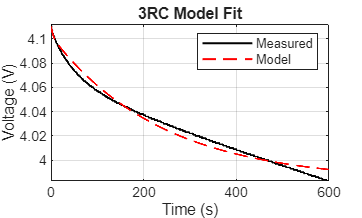


figure;
plot(time, voltage, 'k', 'LineWidth', 1.2); hold on;
plot(time, Vfit, 'r--', 'LineWidth', 1.2);
legend('Measured','Model');
xlabel('Time (s)');
ylabel('Voltage (V)');
grid on;
title('3RC Model Fit');

%% ============================================================
%% LOCAL FUNCTION: 3RC Battery Model
%% ============================================================
function Vsim = simulate_3RC(theta, time, current)

Em = theta(1);
R0 = theta(2);

R  = [theta(3); theta(5); theta(7)];
C  = [theta(4); theta(6); theta(8)];
Tau = R .* C;

dt = mean(diff(time));
N  = numel(time);

Vrc = zeros(3,1);
Vsim = zeros(N,1);

for k = 1:N
    for i = 1:3
        alpha = exp(-dt / Tau(i));
        Vrc(i) = alpha * Vrc(i) + (1 - alpha) * R(i) * current(k);
    end
    Vsim(k) = Em - R0 * current(k) - sum(Vrc);
end
end



**Save Step**

%% ============================================================
%% STEP 9: SAVE PARAMETERS FOR BATTERY BUILDER API
%% ============================================================
disp('STEP 9: Saving parameters for Phase IV (Battery Builder)...');

STEP 9: Saving parameters for Phase IV (Battery Builder)...



% 1. Map theta_hat to specific variables expected by the Builder Script
% theta_hat structure: [Em, R0, R1, C1, R2, C2, R3, C3]

R0_val = theta_hat(2); % Series Resistance

R1_val = theta_hat(3); % Fast Resistance
C1_val = theta_hat(4); % Fast Capacitance

R2_val = theta_hat(5); % Medium Resistance
C2_val = theta_hat(6); % Medium Capacitance

R3_val = theta_hat(7); % Slow Resistance
C3_val = theta_hat(8); % Slow Capacitance

% 2. Define Capacity (Manual Entry)
% Note: Parameter estimation finds Impedance, not Capacity. 
% We must define the cell's physical capacity here for the Builder.
Cap_val = 2.0; % Ah (Standard 18650 Capacity)

% 3. Save to .mat file
% We use the same folder path as your input file
outputFile = "C:\Users\Lenovo\Desktop\Battery_Pack_Design_Project_142\Data\estimated_params.mat";

save(outputFile, 'R0_val', 'R1_val', 'C1_val', ...
    'R2_val', 'C2_val', 'R3_val', 'C3_val', 'Cap_val');

disp(['✓ Success! Parameters saved to: ', char(outputFile)]);

✓ Success! Parameters saved to: C:\Users\Lenovo\Desktop\Battery_Pack_Design_Project_142\Data\estimated_params.mat


disp('  You can now run the "Battery Builder" script.');

  You can now run the "Battery Builder" script.
